### Define symbolic variables

syms phi theta psi phi_dot theta_dot psi_dot x_dot y_dot z_dot x y z real;
syms p q r p_dot q_dot r_dot real;
syms U1 U2 U3 U4 real;

% Define numerical values for parameters
m = 1;  % mass in kg (example value)
g = 9.81; % gravity in m/s^2
Ixx = 8.5532e-3;  % moment of inertia around x-axis (example value)
Iyy = 8.5532e-3;  % moment of inertia around y-axis (example value)
Izz = 1.476e-2;  % moment of inertia around z-axis (example value)
b = 7.66e-5; 
d = 5.63e-6;
l = 0.22;
Omega = 0;


% Define control inputs directly as U1, U2, U3, U4
% U1 = Total thrust
% U2 = Roll torque
% U3 = Pitch torque
% U4 = Yaw torque

% Define relationships between control inputs and motor speeds
% U1_eq = b * (Omega1^2 + Omega2^2 + Omega3^2 + Omega4^2);
% U2_eq = b * (-Omega2^2 + Omega4^2);
% U3_eq = b * (Omega1^2 + Omega3^2);
% U4_eq = d * (-Omega1^2 + Omega2^2 - Omega3^2 + Omega4^2);



% Define state vector X (including positions x, y, z and velocities xdot, ydot, zdot)
X = [x , x_dot , y , y_dot , z , z_dot , phi ,theta , psi , p , q ,r];
disp("State vector:")

State vector:


disp(transpose(X))

$$\left(\begin{array}{c} x\\ \dot{x}\\ y\\ \dot{y}\\ z\\ \dot{z}\\ \varphi \\ \theta \\ \psi \\ p\\ q\\ r \end{array}\right)$$


U =[U1 , U2 , U3 , U4];
disp("Input vector")

Input vector


disp(transpose(U))

$$\left(\begin{array}{c} U_{1}\\ U_{2}\\ U_{3}\\ U_{4} \end{array}\right)$$



% For translational motion
zdd = -g + (cos(phi)*cos(theta)*(1/m)*U1);  % Zdotdot = zdd
xdd = (cos(phi)*sin(theta)*cos(psi) + sin(phi)*sin(psi))*(1/m)*U1;  % xdotdot = xdd
ydd = (cos(phi)*sin(theta)*sin(psi) - sin(phi)*cos(psi))*(1/m)*U1;  % ydotdot = ydd

% Define equations of motion (non-linear) using U1, U2, U3, U4
p_dot = q*r*(Iyy - Izz)/Ixx + (1/Ixx)*U2;  % phidotdot = phidd
q_dot = p*r*(Izz - Ixx)/Iyy + (1/Iyy)*U3;    % thetadotdot = thetadd
r_dot = p*q*(Ixx - Iyy)/Izz + (1/Izz)*U4;      % psidotdot = psidd

phi_dot = p+q*sin(phi)*tan(theta)+r*cos(phi)*tan(theta);
theta_dot = q*cos(phi)-r*sin(phi);
psi_dot = q*sin(phi)*sec(theta)+r*cos(phi)*sec(theta);
% State derivatives (use new variables for second derivatives)
f = [x_dot,xdd,y_dot,ydd,z_dot,zdd,phi_dot,theta_dot,psi_dot,p_dot,q_dot,r_dot];
disp("State equations:")

State equations:


disp(transpose(f))

$$\left(\begin{array}{c} \dot{x}\\ U_{1}\,\left(\sin\left(\varphi \right)\,\sin\left(\psi \right)+\cos\left(\varphi \right)\,\cos\left(\psi \right)\,\sin\left(\theta \right)\right)\\ \dot{y}\\ -U_{1}\,\left(\cos\left(\psi \right)\,\sin\left(\varphi \right)-\cos\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right)\right)\\ \dot{z}\\ U_{1}\,\cos\left(\varphi \right)\,\cos\left(\theta \right)-\frac{981}{100}\\ p+r\,\cos\left(\varphi \right)\,\tan\left(\theta \right)+q\,\sin\left(\varphi \right)\,\tan\left(\theta \right)\\ q\,\cos\left(\varphi \right)-r\,\sin\left(\varphi \right)\\ \frac{r\,\cos\left(\varphi \right)}{\cos\left(\theta \right)}+\frac{q\,\sin\left(\varphi \right)}{\cos\left(\theta \right)}\\ \frac{8227183297206191\,U_{2}}{70368744177664}-\frac{3577976597396889\,q\,r}{4930584106601642}\\ \frac{8227183297206191\,U_{3}}{70368744177664}+\frac{3577976597396889\,p\,r}{4930584106601642}\\ \frac{25000\,U_{4}}{369} \end{array}\right)$$

% Substitute the equilibrium points:
% At equilibrium: phi = theta = psi = phidot = thetadot = psidot = 0, and U1 = m*g (hover condition)

equilibrium_values = [0, 0, 0, 0, 0, 0, 0, 0, 0 , 0 , 0 , 0, m*g, 0, 0, 0]; % hover condition

% Linearize the system around the hover condition (equilibrium points)
A = jacobian(f, X);  % Derivative of f with respect to state variables X
A_eq = subs(A, [X,U] , equilibrium_values ); % Substitute equilibrium


B = jacobian(f, U);  % Derivative of f with respect to input variables U
B_eq = subs(B, [X, U], equilibrium_values); % Substitute equilibrium
B_eq = double(B_eq);

% Define output matrix (assuming full-state feedback)
C = [1 0 0 0 0 0 0 0 0 0 0 0;
    0 0 1 0 0 0 0 0 0 0 0 0;
    0 0 0 0 1 0 0 0 0 0 0 0;
    0 0 0 0 0 0 0 0 1 0 0 0];  % Output is the full state vector

C_simulink = eye(12);
D = zeros(4,4);
D_Simulink = zeros(12,4);

% Display the matrices
disp('Linearized State Matrix A around equilibrium:');

Linearized State Matrix A around equilibrium:


disp(A_eq);

$$\left(\begin{array}{cccccccccccc} 0 & 1 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & \frac{981}{100} & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 1 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & -\frac{981}{100} & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 1 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

A_eq = double(A_eq);
disp('Linearized Input Matrix B around equilibrium:');

Linearized Input Matrix B around equilibrium:


disp(B_eq);

         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
    1.0000         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0  116.9153         0         0
         0         0  116.9153         0
         0         0         0   67.7507




disp('Output Matrix C:');

Output Matrix C:


disp(C);

     1     0     0     0     0     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0     0     0     0
     0     0     0     0     1     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     1     0     0     0



## Q3) Jordan Block Diagonal Form

disp("Block jordan of matrix A is :")

Block jordan of matrix A is :


[V,J] = jordan(A_eq);
disp(J)

     0     1     0     0     0     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     1     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     1     0     0     0     0
     0     0     0     0     0     0     0     0     1     0     0     0
     0     0     0     0     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     1
     0     0     0     0     0     0     0     0     0     0     0     0



## Q4) Transfer Function

syms s t 
phis = inv(s*eye(12)-A_eq); 
TF = C*phis*B_eq %#ok

$$TF = \left(\begin{array}{cccc} 0 & 0 & \frac{8070866814559273371}{7036874417766400\,s^{4}} & 0\\ 0 & -\frac{8070866814559273371}{7036874417766400\,s^{4}} & 0 & 0\\ \frac{1}{s^{2}} & 0 & 0 & 0\\ 0 & 0 & 0 & \frac{25000}{369\,s^{2}} \end{array}\right)$$

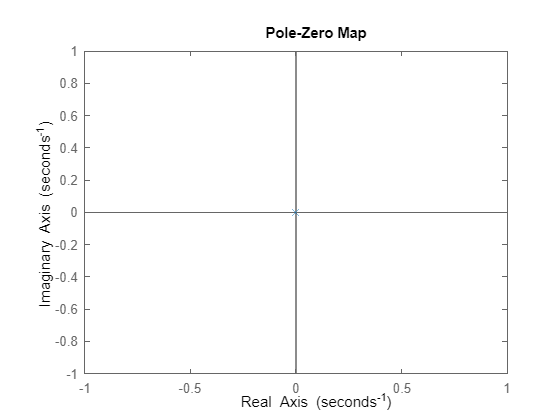

sys=ss(A_eq,B_eq,C,D);
% Display the transfer function matrix
Tf=tf(sys);
figure
pzmap(sys) % all poles on zero


% Get the poles of the MIMO system
poles = pole(sys);

% Display the poles
disp('Poles of the system:');

Poles of the system:


disp(poles);

     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0



% Compute the transmission zeros
transmission_zeros = tzero(sys);

% Display the transmission zeros
disp('Transmission Zeros of the MIMO system:');

Transmission Zeros of the MIMO system:


disp(transmission_zeros);
disp('This sys doesnt have any Zeros')

This sys doesnt have any Zeros


##   Q5)  Internal stability


% Check eigenvalues of A
eigenvalues = eig(A_eq);
disp('Eigenvalues of A:');

Eigenvalues of A:


disp(eigenvalues);

     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0



% Ensure the A matrix is stable
if any(real(eigenvalues) >= 0)
    disp('The system is not stable. Lyapunov stability check is not applicable.');
else
    % Define the Lyapunov equation: A'P + PA = -Q
    Q = eye(size(A_eq)); % Define a positive definite matrix Q
    try
        P = lyap(A_eq', Q); % Solve the Lyapunov equation
        disp('Lyapunov matrix P:');
        disp(P);

        % Check if P is positive definite
        if all(eig(P) > 0)
            disp('The Lyapunov matrix P is positive definite, confirming stability.');
        else
            disp('The Lyapunov matrix P is not positive definite.');
        end
    catch ME
        disp('Error solving Lyapunov equation:');
        disp(ME.message);
    end
end

The system is not stable. Lyapunov stability check is not applicable.


## Q6) State transition matrix

phi_L = inv(s*eye(length(A_eq))-A_eq);
disp(phi_L)

$$\begin{array}{l} \left(\begin{array}{cccccccccccc} \frac{1}{s} & \frac{1}{s^{2}} & 0 & 0 & 0 & 0 & 0 & \sigma_{1} & 0 & 0 & \sigma_{2} & 0\\ 0 & \frac{1}{s} & 0 & 0 & 0 & 0 & 0 & \sigma_{3} & 0 & 0 & \sigma_{1} & 0\\ 0 & 0 & \frac{1}{s} & \frac{1}{s^{2}} & 0 & 0 & -\sigma_{1} & 0 & 0 & -\sigma_{2} & 0 & 0\\ 0 & 0 & 0 & \frac{1}{s} & 0 & 0 & -\sigma_{3} & 0 & 0 & -\sigma_{1} & 0 & 0\\ 0 & 0 & 0 & 0 & \frac{1}{s} & \frac{1}{s^{2}} & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & \frac{1}{s} & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & \frac{1}{s} & 0 & 0 & \frac{1}{s^{2}} & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & \frac{1}{s} & 0 & 0 & \frac{1}{s^{2}} & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & \frac{1}{s} & 0 & 0 & \frac{1}{s^{2}}\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & \frac{1}{s} & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & \frac{1}{s} & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & \frac{1}{s} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{981}{100\,s^{3}}\\ \sigma_{2}=\frac{981}{100\,s^{4}}\\ \sigma_{3}=\frac{981}{100\,s^{2}} \end{array}$$

phi_t = ilaplace(phi_L);
disp(phi_t)

$$\begin{array}{l} \left(\begin{array}{cccccccccccc} 1 & t & 0 & 0 & 0 & 0 & 0 & \sigma_{1} & 0 & 0 & \sigma_{2} & 0\\ 0 & 1 & 0 & 0 & 0 & 0 & 0 & \frac{981\,t}{100} & 0 & 0 & \sigma_{1} & 0\\ 0 & 0 & 1 & t & 0 & 0 & -\sigma_{1} & 0 & 0 & -\sigma_{2} & 0 & 0\\ 0 & 0 & 0 & 1 & 0 & 0 & -\frac{981\,t}{100} & 0 & 0 & -\sigma_{1} & 0 & 0\\ 0 & 0 & 0 & 0 & 1 & t & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 1 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 1 & 0 & 0 & t & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 & 0 & 0 & t & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 & 0 & 0 & t\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{981\,t^{2}}{200}\\ \sigma_{2}=\frac{327\,t^{3}}{200} \end{array}$$

x0 = transpose([0.1 0.1 3 1 4 0.34 1 0.01 1 0.1 3 1]) ;
Uin_s = transpose([1/s ,1/s,1/s,1/s]);
X = phi_L*x0 + phi_L*B_eq*Uin_s;
Y = C*X ;
y_t = ilaplace(Y)

$$y\_t = \begin{array}{l} \left(\begin{array}{c} \sigma_{1}+\frac{981\,t^{3}}{200}+\frac{981\,t^{2}}{20000}+\frac{t}{10}+\frac{1}{10}\\ -\sigma_{1}-\frac{327\,t^{3}}{2000}-\frac{981\,t^{2}}{200}+t+3\\ \frac{t^{2}}{2}+\frac{17\,t}{50}+4\\ \frac{12500\,t^{2}}{369}+t+1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{2690288938186424457\,t^{4}}{56294995342131200} \end{array}$$

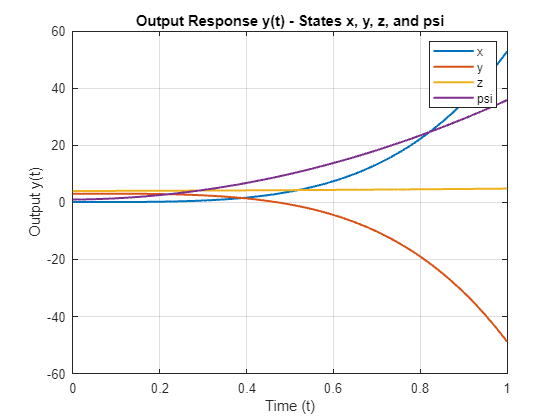

T = 0:0.01:1;
y_numeric = double(subs(y_t, t, T));

plot(T, y_numeric(1, :), 'DisplayName', 'x', 'LineWidth', 1.5);
hold on;
plot(T, y_numeric(2, :), 'DisplayName', 'y', 'LineWidth', 1.5);
plot(T, y_numeric(3, :), 'DisplayName', 'z', 'LineWidth', 1.5);
plot(T, y_numeric(4, :), 'DisplayName', 'psi', 'LineWidth', 1.5);
hold off;

xlabel('Time (t)');
ylabel('Output y(t)');
title('Output Response y(t) - States x, y, z, and psi');
legend('show');  
grid on;

## **Q8)Nonlinear simulink**

Condition_1 = transpose([0.2 0.2 0.2 0.2 0.2 0.2 0.2 0.2 0.2 0.2 0.2 0.2]);
Condition_0 = transpose([0 0 0 0 0 0 0 0 0 0 0 0]);

x_0 = phi_t*Condition_1;
yout = C*x_0

$$yout = \left(\begin{array}{c} \frac{327\,t^{3}}{1000}+\frac{981\,t^{2}}{1000}+\frac{t}{5}+\frac{1}{5}\\ -\frac{327\,t^{3}}{1000}-\frac{981\,t^{2}}{1000}+\frac{t}{5}+\frac{1}{5}\\ \frac{t}{5}+\frac{1}{5}\\ \frac{t}{5}+\frac{1}{5} \end{array}\right)$$

## **Q9) Simulink**

## Q10) Controllability and Observability Matrix

n = size(A_eq, 1); % Number of state


Ctrb = ctrb(A_eq, B_eq);
Obsv = obsv(A_eq, C);


rank_Ctrb = rank(Ctrb);

rank_Obsv = rank(Obsv);


disp('Rank of Controllability Matrix:');

Rank of Controllability Matrix:


disp(rank_Ctrb);

    12



disp('Rank of Observability Matrix:');

Rank of Observability Matrix:


disp(rank_Obsv);

    12



if rank_Ctrb == n
    disp('The system is controllable.');
else
    disp('The system is not controllable.');
end

The system is controllable.


if rank_Obsv == n
    disp('The system is observable.');
else
    disp('The system is not observable.');
end

The system is observable.


% Compute eigenvalues and eigenvectors
[eigVec_C, eigVal_C] = eig(A_eq);
control_poles = diag(eigVal_C(rank(Ctrb) == n));

[eigVec_O, eigVal_O] = eig(A_eq');
observable_poles = diag(eigVal_O(rank(Obsv) == n));

% Display Results
disp('Controllable Poles:');

Controllable Poles:


disp(control_poles);

     0



disp('Observable Poles:');

Observable Poles:


disp(observable_poles);

     0



eigenvalues = eig(A_eq);

% Display eigenvalues
disp('Eigenvalues of A:');

Eigenvalues of A:


disp(eigenvalues);

     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0




% Check stabilizability
if all(real(eigenvalues(rank(Ctrb) == n)) < 0)
    disp('The system is stabilizable.');
else
    disp('The system is not stabilizable.');
end

The system is not stabilizable.



% Check detectability
if all(real(eigenvalues(rank(Obsv) == n)) < 0)
    disp('The system is detectable.');
else
    disp('The system is not detectable.');
end

The system is not detectable.


## **Q11) Kalman Decomposition**

%% Kalman Decomposition

% Controllability 
ControllabilityMatrix = ctrb(A_eq, B_eq);
rank_controllability = rank(ControllabilityMatrix);
disp('Rank of Controllability Matrix:');

Rank of Controllability Matrix:


disp(rank_controllability);

    12




%  Observability 
ObservabilityMatrix = obsv(A_eq, C);
rank_observability = rank(ObservabilityMatrix);
disp('Rank of Observability Matrix:');

Rank of Observability Matrix:


disp(rank_observability);

    12




% T Matrix
[Ac, Bc, Cc, T_c, k] = ctrbf(A_eq, B_eq, C);
disp('Transformation matrix for controllability decomposition (T_c):');

Transformation matrix for controllability decomposition (T_c):


disp(T_c);

    -1     0     0     0     0     0     0     0     0     0     0     0
     0     0    -1     0     0     0     0     0     0     0     0     0
     0    -1     0     0     0     0     0     0     0     0     0     0
     0     0     0    -1     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     1     0     0     0     0     0
     0     0     0     0     0     0     0     1     0     0     0     0
     0     0     0     0     0     0     0     0     1     0     0     0
     0     0     0     0     1     0     0     0     0     0     0     0
     0     0     0     0     0    -1     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0    -1
     0     0     0     0     0     0     0     0     0     0    -1     0
     0     0     0     0     0     0     0     0     0    -1     0     0




% DECOMPOSITION
A_cc = Ac(1:rank_controllability, 1:rank_controllability); % Controllable part of A
A_uu = Ac(rank_controllability+1:end, rank_controllability+1:end); % Uncontrollable part of A

B_cc = Bc(1:rank_controllability, :); % Input affecting controllable subspace
B_uc = Bc(rank_controllability+1:end, :); % Input affecting uncontrollable subspace

C_cc = Cc(:, 1:rank_controllability); % Output from controllable subspace
C_uc = Cc(:, rank_controllability+1:end); % Output from uncontrollable subspace

disp('Controllable A_cc:');

Controllable A_cc:


disp(A_cc);

  Columns 1 through 9

         0         0    1.0000         0         0         0         0         0         0
         0         0         0    1.0000         0         0         0         0         0
         0         0         0         0         0   -9.8100         0         0         0
         0         0         0         0    9.8100         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0   -1.0000
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0       


disp('Uncontrollable A_uu:');

Uncontrollable A_uu:


disp(A_uu);

disp('Controllable Input B_cc:');

Controllable Input B_cc:


disp(B_cc);

         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
   -1.0000         0         0         0
         0         0         0  -67.7507
         0         0 -116.9153         0
         0 -116.9153         0         0




disp('Uncontrollable Input B_uc:');

Uncontrollable Input B_uc:


disp(B_uc);

disp('Observable Output C_cc:');

Observable Output C_cc:


disp(C_cc);

    -1     0     0     0     0     0     0     0     0     0     0     0
     0    -1     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     1     0     0     0     0
     0     0     0     0     0     0     1     0     0     0     0     0




disp('Unobservable Output C_uc:');

Unobservable Output C_uc:


disp(C_uc);

## Phase 2 

% Create state-space system from linearized matrices
sys = ss(double(A_eq), double(B_eq), C, D);


% irreducible (minimal) subsystem
sys_reduced = minreal(sys);

disp('Reduced (Minimal) System:');

Reduced (Minimal) System:


disp(sys_reduced);

  4×4 ss array with properties:

                A: [12×12 double]
                B: [12×4 double]
                C: [4×12 double]
                D: [4×4 double]
                E: []
           Scaled: 0
        StateName: {12×1 cell}
        StatePath: {12×1 cell}
        StateUnit: {12×1 cell}
    InternalDelay: [0×1 double]
       InputDelay: [4×1 double]
      OutputDelay: [4×1 double]
        InputName: {4×1 cell}
        InputUnit: {4×1 cell}
       InputGroup: [1×1 struct]
       OutputName: {4×1 cell}
       OutputUnit: {4×1 cell}
      OutputGroup: [1×1 struct]
            Notes: [0×1 string]
         UserData: []
             Name: ''
               Ts: 0
         TimeUnit: 'seconds'
     SamplingGrid: [1×1 struct]



% reduced matrices A, B, C, and D
[A_reduced, B_reduced, C_reduced, D_reduced] = ssdata(sys_reduced);

% Display
disp('Reduced State Matrix A:');

Reduced State Matrix A:


disp(A_reduced);

  Columns 1 through 9

         0    1.0000         0         0         0         0         0         0         0
         0         0         0         0         0         0         0    9.8100         0
         0         0         0    1.0000         0         0         0         0         0
         0         0         0         0         0         0   -9.8100         0         0
         0         0         0         0         0    1.0000         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0       

disp('Reduced Input Matrix B:');

Reduced Input Matrix B:


disp(B_reduced);

         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
    1.0000         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0  116.9153         0         0
         0         0  116.9153         0
         0         0         0   67.7507



disp('Reduced Output Matrix C:');

Reduced Output Matrix C:


disp(C_reduced);

     1     0     0     0     0     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0     0     0     0
     0     0     0     0     1     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     1     0     0     0



disp('Reduced Direct Transmission Matrix D:');

Reduced Direct Transmission Matrix D:


disp(D_reduced);

     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0



## **State Feedback**

%Poles = [-0.5 + 1i*0.5,-2,-2.1,-2.1,-0.5-1i*0.5,-2.5,-2.5,-2.4,-2.3,-2.3,-2.03,-2.03];
Poles = [-0.5+0.5j ,-9.3 , -0.5-0.5j , -9 ,-9.3,-9.3,-9.7,-9.7,-9.7,-9.7,-9.9,-9.9];
Kfeedback = place(A_eq,B_eq,Poles)

Kfeedback =    11.1746   16.4435  -15.2068   -9.0606   90.1194   18.9907   13.6594   29.9914   -0.0097    0.6270    1.4976   -0.0010
   -0.3570   -0.1202   -0.0064   -0.7780    0.0002    0.0000    2.3772   -0.1312    0.0000    0.2470   -0.0048    0.0000
    0.7452    0.9921   -0.8094   -0.2467    0.0003    0.0000    0.2460    2.5794    0.0000    0.0083    0.2535    0.0000
    0.0179    0.0263   -0.0243   -0.0145   -0.0001   -0.0000    0.0218    0.0479    1.3315    0.0010    0.0024    0.2804


A_feedback = A_eq - B_eq*Kfeedback

A_feedback =          0    1.0000         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0    9.8100         0         0         0         0
         0         0         0    1.0000         0         0         0         0         0         0         0         0
         0         0         0         0         0         0   -9.8100         0         0         0         0         0
         0         0         0         0         0    1.0000         0         0         0         0         0         0
  -11.1746  -16.4435   15.2068    9.0606  -90.1194  -18.9907  -13.6594  -29.9914    0.0097   -0.6270   -1.4976    0.0010
         0         0         0         0         0         0         0         0         0    1.0000         0         0
         0         0         0         0         0         0         0         0         0         0    1.0000         0
         0         

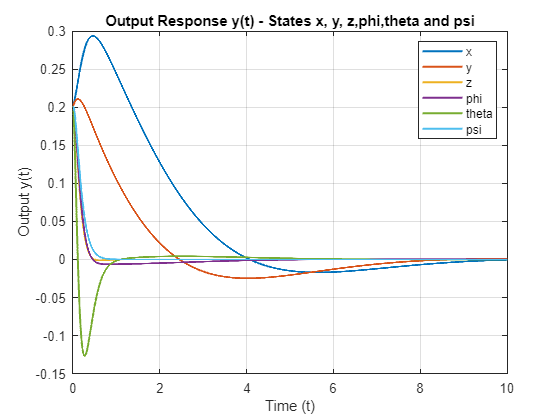

C_final = [1 0 0 0 0 0 0 0 0 0 0 0 ;
            0 0 1 0 0 0 0 0 0 0 0 0 ;
            0 0 0 0 1 0 0 0 0 0 0 0 ;
            0 0 0 0 0 0 1 0 0 0 0 0 
            0 0 0 0 0 0 0 1 0 0 0 0 
            0 0 0 0 0 0 0 0 1 0 0 0 ];

% Parameters and matrices
T_new = 0:0.001:10;  % Time vector
n = size(A_feedback, 1); % Number of states
I = eye(n);

% Compute state transition matrix numerically using expm
phi_t_numeric = arrayfun(@(t) expm(A_feedback * t), T_new, 'UniformOutput', false);

% Compute the state response X_new numerically
X_numeric = cellfun(@(phi) phi * Condition_1, phi_t_numeric, 'UniformOutput', false);

% Compute the output response y_new
y_numeric_new = cellfun(@(X) C_final * X, X_numeric, 'UniformOutput', false);

% Convert to matrix form for plotting
y_numeric_new = cell2mat(reshape(y_numeric_new, 1, 1, []));
y_numeric_new = reshape(y_numeric_new, size(C_final, 1), []);

% Plot
plot(T_new, y_numeric_new(1, :), 'DisplayName', 'x', 'LineWidth', 1.5); hold on;
plot(T_new, y_numeric_new(2, :), 'DisplayName', 'y', 'LineWidth', 1.5);
plot(T_new, y_numeric_new(3, :), 'DisplayName', 'z', 'LineWidth', 1.5);
plot(T_new, y_numeric_new(4, :), 'DisplayName', 'phi', 'LineWidth', 1.5);
plot(T_new, y_numeric_new(5, :), 'DisplayName', 'theta', 'LineWidth', 1.5);
plot(T_new, y_numeric_new(6, :), 'DisplayName', 'psi', 'LineWidth', 1.5);
hold off;

xlabel('Time (t)');
ylabel('Output y(t)');
title('Output Response y(t) - States x, y, z,phi,theta and psi');
legend('show');
grid on;

## **LQR**


%Q1 = diag([0.1, 0.1, 0.1, 0.1, 1, 50, 50000, 50000, 0.1, 0, 0, 0]);
Q1 = diag([15, 3, 15, 3, 100, 15, 80, 80, 10, 0, 0, 0]);
R1 = 3*diag([1, 1, 5, 5]);

[K_LQR1, ~, P1_LQR1] = lqr(A_eq,B_eq,Q1,R1)

K_LQR1 =     0.0000    0.0000    0.0000    0.0000    5.7735    4.0678   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000
   -0.0000   -0.0000   -2.2361   -1.9599   -0.0000   -0.0000    6.2328   -0.0000   -0.0000    0.3265   -0.0000   -0.0000
    1.0000    0.9048   -0.0000   -0.0000    0.0000   -0.0000    0.0000    3.0349    0.0000   -0.0000    0.2279    0.0000
   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.8165    0.0000   -0.0000    0.1553


P1_LQR1 =   -1.7396 + 1.1053i
  -1.7396 - 1.1053i
  -1.7397 + 1.1052i
  -1.7397 - 1.1052i
  -2.0339 + 1.2794i
  -2.0339 - 1.2794i
  -5.2592 + 5.2592i
  -5.2592 - 5.2592i
 -11.5799 +11.6576i
 -11.5799 -11.6576i


A_feedback_LQR = A_eq - B_eq*K_LQR1

A_feedback_LQR =          0    1.0000         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0    9.8100         0         0         0         0
         0         0         0    1.0000         0         0         0         0         0         0         0         0
         0         0         0         0         0         0   -9.8100         0         0         0         0         0
         0         0         0         0         0    1.0000         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000   -0.0000   -5.7735   -4.0678    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000
         0         0         0         0         0         0         0         0         0    1.0000         0         0
         0         0         0         0         0         0         0         0         0         0    1.0000         0
         0     

eig(A_feedback_LQR)

ans =  -11.5799 +11.6576i
 -11.5799 -11.6576i
 -17.3485 +17.4004i
 -17.3485 -17.4004i
  -1.7397 + 1.1052i
  -1.7397 - 1.1052i
  -5.2592 + 5.2592i
  -5.2592 - 5.2592i
  -1.7396 + 1.1053i
  -1.7396 - 1.1053i


## **Static Pre-compensator **

G_0 = -C_final/(A_feedback) * B_eq ;
inv_G_0 = pinv(G_0);
inv_G0 = inv_G_0( : , [1 , 2 ,3 ,6]);
B_feedback = B_eq * inv_G0;
phi_s_feedback = inv(s*eye(12) - A_feedback);
%X_feedback = phi_s_feedback * x0 + phi_s_feedback*B_feedback*Uin_s;
%Y_feedback = C_final*X_feedback;


## **Static Pre-compensator With LQR **

G_0_LQR = -C_final/(A_feedback_LQR) * B_eq ;
inv_G_0_LQR = pinv(G_0_LQR);
inv_G0_LQR = inv_G_0_LQR( : , [1 , 2 ,3 ,6]);

## **Dynamic Pre-compensator with LQR**

Q = diag([10 1 10 1 40 3 10 10 1 1 1 1 500 3000 3000 400 ]);
% 4 ta akhari moheman ahari ham mohrm nis
R = diag([1, 5, 1, 1]);

Ai = [A_eq, zeros(12, 4); -C_final([1 2 3 6], 1:12), zeros(4, 4)];
Bi = [B_eq; zeros(4, 4)];
rank(ctrb(Ai,Bi))

ans = 16

[K_LQR,~,P_LQR] = lqr(Ai,Bi,Q,R)

K_LQR =     0.0000    0.0000    0.0000    0.0000   30.2043    7.9629   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000  -54.7723   -0.0000
    0.0000    0.0000  -14.2463   -4.1020   -0.0000   -0.0000    6.6886    0.0000   -0.0000    0.5607   -0.0000   -0.0000   -0.0000   24.4949    0.0000    0.0000
   16.6087    5.9446   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   11.6150   -0.0000   -0.0000    1.0948    0.0000  -22.3607    0.0000    0.0000    0.0000
   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    6.6912    0.0000   -0.0000    1.0943    0.0000    0.0000   -0.0000  -20.0000


P_LQR = 1.0e+02 *

  -0.0182 + 0.0323i
  -0.0182 - 0.0323i
  -0.0203 + 0.0419i
  -0.0203 - 0.0419i
  -0.0208 + 0.0317i
  -0.0208 - 0.0317i
  -0.0320 + 0.0313i
  -0.0320 - 0.0313i
  -0.0375 + 0.0138i
  -0.0375 - 0.0138i


K_d_LQR = K_LQR(:,1:12)

K_d_LQR =     0.0000    0.0000    0.0000    0.0000   30.2043    7.9629   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000
    0.0000    0.0000  -14.2463   -4.1020   -0.0000   -0.0000    6.6886    0.0000   -0.0000    0.5607   -0.0000   -0.0000
   16.6087    5.9446   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   11.6150   -0.0000   -0.0000    1.0948    0.0000
   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    6.6912    0.0000   -0.0000    1.0943


K_q_LQR = K_LQR(:,12+1:12+4)

K_q_LQR =    -0.0000   -0.0000  -54.7723   -0.0000
   -0.0000   24.4949    0.0000    0.0000
  -22.3607    0.0000    0.0000    0.0000
    0.0000    0.0000   -0.0000  -20.0000


## **Full Order Observer**

C_eq = C_final([1 2 3 6], 1:12);
poles_obsv = [-20 ,-20 , -20 , -21 ,-21,-21,-21.5,-21.5,-21.5,-22,-22,-22];
L = place(A_eq.',C_eq.',poles_obsv).'

L = 1.0e+04 *

    0.0084    0.0000   -0.0000   -0.0000
    0.2676    0.0000   -0.0000   -0.0000
   -0.0000    0.0084   -0.0000    0.0000
   -0.0000    0.2676   -0.0000    0.0000
    0.0000    0.0000    0.0042   -0.0001
    0.0000    0.0000    0.0450   -0.0017
    0.0000   -0.3839    0.0000   -0.0000
    0.3839    0.0000   -0.0000   -0.0000
   -0.0000   -0.0000   -0.0001    0.0042
    0.0000   -2.0251    0.0000   -0.0000


A_eq-L*C_eq

ans = 1.0e+04 *

   -0.0084    0.0001   -0.0000         0    0.0000         0         0         0    0.0000         0         0         0
   -0.2676         0   -0.0000         0    0.0000         0         0    0.0010    0.0000         0         0         0
    0.0000         0   -0.0084    0.0001    0.0000         0         0         0   -0.0000         0         0         0
    0.0000         0   -0.2676         0    0.0000         0   -0.0010         0   -0.0000         0         0         0
   -0.0000         0   -0.0000         0   -0.0042    0.0001         0         0    0.0001         0         0         0
   -0.0000         0   -0.0000         0   -0.0450         0         0         0    0.0017         0         0         0
   -0.0000         0    0.3839         0   -0.0000         0         0         0    0.0000    0.0001         0         0
   -0.3839         0   -0.0000         0    0.0000         0         0         0    0.0000         0    0.0001         0
    0.0000     

## **Reduced Order Observer**

q = rank(C_eq)

q = 4


F = [ ...  
    -20,   -20,   -20,   -21,   -21,   15,   -21.5, -21.5;   
     0,   -20,   -20,   -21,   -21,   -21,   -21.5, -21.5;   
     0,     0,   -20,   -21,   -21,   -21,   -21.5, -21.5;   
     0,     0,     0,   -21,   -21,   -21,   -21.5, -21.5;   
     0,     0,     0,     0,   -21,   -21,   -21.5, -21.5;   
     0,     0,     0,     0,     0,   -21,   -21.5, -21.5;   
     0,     0,     0,     0,     0,     0,   -21.5, -21.5;   
     0,     0,     0,     0,     0,     0,      0,   -21.5  
];
L_RO = 100*[1 2 1 14;
     3 3 2.5 6.3;
     2 3 5.6 1.2;
     2 3 3 5;
     2 4 45 5.6;
     2 6 7 9;
     2 7 5 9;
     2 7 9 2.5]   % L_(n-q)*q

L_RO =          100         200         100        1400
         300         300         250         630
         200         300         560         120
         200         300         300         500
         200         400        4500         560
         200         600         700         900
         200         700         500         900
         200         700         900         250


% F = [ ...  
%     -20,   1,      1,    -1,   -21,     3,       4,     0;   
%      0,   -20,    11,    10,     1,     0,       0,     0;   
%      0,     0,   -20,    20,     1,     1,       1,     0;   
%      0,     0,     0,   -21,    10,     1,       1,     0;   
%      0,     0,     0,     0,   -21,    21,       1,     0;   
%      0,     0,     0,     0,     0,   -21,      10,     0;   
%      0,     0,     0,     0,     0,     0,   -21.5,    10;   
%      0,     0,     0,     0,     0,     0,      0,   -21.5  
% ];
% L_RO = 200*[3 2 1 5; 
%       5 2 2.5 6.3;
%      -2 -10 5.6 1.2; 
%      11 -3 3 5;
%      -2 2.5 3 5.6; 
%      -9 2.5 7 9;
%      2 2.75 5 9;
%      2 -7 9 2.5]   % L_(n-q)*q
C

C =      1     0     0     0     0     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0     0     0     0
     0     0     0     0     1     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     1     0     0     0


ctrb_mat = ctrb(F,L_RO);
rank_ctr = rank(ctrb_mat)

rank_ctr = 8

T_O = lyap(-F,A_eq,-L_RO*C)  % T_(n-q)*n

T_O =   -10.0000    0.7500  -13.5714    1.0867    9.6429   -3.6682   -0.5496   -0.1267   38.5000    0.2033   -0.0387    1.9414
    5.0000   -0.2500         0         0  -15.5000    1.4250    0.1168    0.1226   25.5000   -0.0061   -0.0061   -2.2250
         0         0         0   -0.2381   13.0000  -10.6500   -0.0056         0  -19.0000   -0.0103   -0.0000    0.8071
         0         0   -4.7619   -0.2268 -200.0000   18.1406   -0.2119         0   -2.8571    0.0101    0.0000   -0.6349
         0         0   -9.5238    0.2268  180.9524   -8.1633   -0.0000         0  -16.1905   -0.0286    0.0096    0.7710
         0         0   -4.7619    0.2268    9.5238   -1.3395   -0.6015    0.2021         0    0.0944   -0.0284    1.4396
         0    0.4327         0    1.5143  -18.6047    2.8123    1.3819   -0.3948   30.2326   -0.0964    0.0275   -0.8653
    9.3023   -0.4327   32.5581   -1.5143   41.8605   -1.9470   -0.6910    0.1974   11.6279    0.0321   -0.0092   -0.5408


mat2 = [C; T_O]

mat2 =     1.0000         0         0         0         0         0         0         0         0         0         0         0
         0         0    1.0000         0         0         0         0         0         0         0         0         0
         0         0         0         0    1.0000         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0    1.0000         0         0         0
  -10.0000    0.7500  -13.5714    1.0867    9.6429   -3.6682   -0.5496   -0.1267   38.5000    0.2033   -0.0387    1.9414
    5.0000   -0.2500         0         0  -15.5000    1.4250    0.1168    0.1226   25.5000   -0.0061   -0.0061   -2.2250
         0         0         0   -0.2381   13.0000  -10.6500   -0.0056         0  -19.0000   -0.0103   -0.0000    0.8071
         0         0   -4.7619   -0.2268 -200.0000   18.1406   -0.2119         0   -2.8571    0.0101    0.0000   -0.6349
         0         0   -9

det(mat2)

ans = -1.1116e-04

inv_mat2 = inv(mat2)

inv_mat2 = 1.0e+04 *

    0.0001   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0185    0.0369    0.1015    0.0441   -0.0001   -0.0002   -0.0007   -0.0011   -0.0014   -0.0014   -0.0017   -0.0019
    0.0000    0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0035   -0.0031   -0.0212   -0.0070    0.0000    0.0002    0.0003    0.0004    0.0005    0.0003    0.0004    0.0003
         0         0    0.0001         0         0         0         0         0         0         0         0         0
    0.0000   -0.0000    0.0010    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000
    0.0081    0.0031   -0.0077    0.0059   -0.0002   -0.0005   -0.0013   -0.0013   -0.0012   -0.0006   -0.0008   -0.0008
    0.0406    0.0606    0.0161    0.0749   -0.0005   -0.0013   -0.0041   -0.0041   -0.0037   -0.0029   -0.0041   -0.0042
         0

Q_1 = inv_mat2(:,1:q)

Q_1 = 1.0e+04 *

    0.0001   -0.0000   -0.0000   -0.0000
    0.0185    0.0369    0.1015    0.0441
    0.0000    0.0001   -0.0000   -0.0000
   -0.0035   -0.0031   -0.0212   -0.0070
         0         0    0.0001         0
    0.0000   -0.0000    0.0010    0.0000
    0.0081    0.0031   -0.0077    0.0059
    0.0406    0.0606    0.0161    0.0749
         0         0         0    0.0001
    0.0540   -0.0146   -0.6555   -0.0387


Q_2 = inv_mat2(:,q+1:n)

Q_2 =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
   -0.5140   -2.4307   -7.1748  -10.6978  -13.7113  -14.0625  -17.3750  -19.1728
   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.4149    1.5990    2.7176    3.6103    4.5069    3.0116    3.6056    3.4009
         0         0         0         0         0         0         0         0
   -0.0188   -0.0384   -0.0568   -0.0033   -0.0546    0.0129   -0.0090   -0.0192
   -1.7006   -5.2140  -12.6224  -12.6546  -11.7249   -5.6003   -7.8162   -7.7515
   -4.8994  -13.2031  -41.0930  -41.1577  -37.2839  -29.3104  -40.9945  -41.8585
         0         0         0         0         0         0         0         0
   -6.5157  -45.5721 -133.2946 -106.1264  -68.9895  -45.4453  -55.6153  -40.5777
